# Fourier Transforms and Spectral Analysis

# Fourier Transform of PDEs- Analytics

We will start off by learning how to perform a fast fourier transform, which lies at the heart of the Spectral Method of analysis of PDE or ODE. However, we need to understand why fourier analysis will prove so useful or how to do spectral method for analysing PDEs

The cornerstone formula of fourier transform is:


$$$f(t)=\int \mathrm{d}\omega\tilde f(\omega)e^{\iota \omega t}$ (temporal FT)

$$



$$$f(x)=\int \mathrm{d}\kappa\tilde f(\kappa)e^{\iota \kappa x}$ (spatial FT)$$


The key idea of the spectral method is to take any differential equation and perform a Fourier Transform on both sides! The method seems simple and in-fact you are true to think that. However, its usefulness is quite elusive. We will see how useful and insightful it is. 

Take any differential equation. It will obviously will have the differential operator of both w.r.t. space and time. The neat part about performing fourier transform is that we are essentially **expanding the function as the eigen-functions** of the $\nabla$ operator(and its higher power $\nabla^{2}$, $\nabla^{3}$, $\nabla^{4}$,...). By expanding the function as such, we are essentially getting rid of the spatial derivative-We turned it into algebra! [***Note: ***Plane waves(i.e. $e^{\iota \kappa \cdot r}$) are the eigen-functions of the above operators. If it non-trivial to you, please check!]

Essentially, we are then only left with temporal derivatives, some terms involving powers of $\iota \kappa$ and the fourier transformed function. We turned a PDE into an ODE. Is it not convenient?

However, that is not the only merit of this formalism. There physical insights of the underlying problem becomes very clear too. We shall see that as we progress onto solving the Diffusion equation and Fokker Planck equation, etc... 

Say I have the following PDE:


$$$$\frac{\partial \psi}{\partial t}=\nabla\psi+\nabla^2\psi-\nabla^4\psi \cdots(1)$$$$


Looks scary, right? However, lets perform a Fourier Transform of the above PDE. We get the following:


$$$$\frac{\partial\tilde \psi}{\partial t}=(\iota\kappa-\kappa^2-\kappa^4)\tilde\psi\cdots(2)  \text{(Spatial FT)}$$
$$



$$$$\iota \omega=(\iota\kappa-\kappa^2-\kappa^4)\cdots(3) \text{(Temporal and Spatial FT)}$$   
$$



$$$$\hat{\psi}(\kappa, t) = \hat{\psi}(\kappa, 0) \cdot e^{i\kappa t} \cdot e^{-(\kappa^2 + \kappa^4)t}= \hat{\psi}(\kappa, 0) \cdot e^{i\omega t}\cdots(4) \text{(evolution of each k-mode)}$$$$


### 1) Does the above function conserve Mass?

    Analyse the K=0 mode. Taking the inverse Spatial FT, we get 


$$\tilde\psi(k)=\int\mathrm{d}x \psi(x)e^{-\iota\kappa x}$$



$$\tilde\psi(0)=\int\mathrm{d}x \psi(s)$$


which conveniently is the total mass!

Here, if we analyse the k=0 mode of eq(2), we get 


$$\frac{\partial\tilde\psi(k=0)}{\partial t}=0$$


which means that the mass is indeed conserved. If the RHS of eq(2) was inhomogeneous in the variable $\kappa$ then the equation will not conserve particle. 

### 2) Is the above equation dissipative, oscillatory? 

    Taking eq(2), the $-\kappa^2 \text{ and} -\kappa^4$ contribute to the dissipative behaviour, whereas, the $\iota \kappa$ contribute to the oscillatory behaviour. We need further analysis of the terms to see which term dominates at what scales. Let's calculate the crossover point where the behaviours will be almost equal, for which we need to find positive roots of the below equation:


$$|\text{Imaginary Part}| = |\text{Real Part}|$$


$\kappa=\kappa^2+\kappa^4 \Longrightarrow \kappa^3 + \kappa - 1 = 0$, ($\kappa=0$ is the trivial soln, so we ignore it!)

If we solve the above, we get the value of $\kappa \approx 0.68$. Below this the imaginary part, i.e. oscillatory part dominates. and above this, the dissipative part dominates. We can summarize it as follows:

### 3) Is the above equation dispersive?

Observe eq(3), i.e


$$$\iota \omega=(\iota\kappa-\kappa^2-\kappa^4)$$$
 


$$\omega=(\kappa+\iota\kappa^2+\iota\kappa^4)$$



$$Re(\omega)=\kappa, Im(\omega)=\kappa^2+\kappa^4$$


From eq(4), we get the time evolution of each k-mode, the contribution of the Real and Imaginary part will be as follows:

$Re(\omega)$ :  $\hat{\psi}(\kappa, 0) \cdot e^{\iota Re(\omega)t}=\hat{\psi}(\kappa, 0) \cdot e^{\iota \kappa t}$

$Im(\omega)$ : $\hat{\psi}(\kappa, 0) \cdot e^{\iota Im(\omega)t}=\hat{\psi}(\kappa, 0) \cdot e^{-(\kappa^2+\kappa^4)t}$

**The contribution only from the imaginary part** clearly causes the decay of each k-mode, and higher the k-mode, higher the rate of decay of mode. In real space, it means that the higher frequencies decay extremely fast. Hence, the wave-packet will broaden due to this dissipation. 

### Viewpoint 1(Signal-Processing Viewpoint)

I can combine both the broadening effects under one umbrella term- **dispersion.**

The broadening caused by the real part(**Phase-based broadening**) and Imaginary part(**Amplitude-based**) are not differentiated. We say that as long as broadening happens, dispersion happens. Since we do not want to differentiate the contribution from the real and imaginary part, we will say that dispersion happens, as long as, 


$$$ |\omega(\kappa)|=\sqrt{Re(\omega)^2+Im(\omega)^2}=\sqrt{\kappa^2+(\kappa^2+\kappa^4)^2}$$$


Since the relation of $|\omega|$ is non-linear in $\kappa$, so broadening happens, hence, in this viewpoint,  **dispersion** happens. If It were linear in $\kappa$, no type of broadening will happen. 

This viewpoint is useful in **signal processing **and related fields-If you send a "bit" of data (a light pulse) down a cable and it arrives twice as wide,  the pulse is "dispersed."  Whether it happened because of the glass's refractive index (dispersion) or because the high-frequency edges were filtered out (dissipation), the result is the same: the data is corrupted.

### Viewpoint 2(Optics Viewpoints)

Here, the **phase-based **and **amplitude-based **dissipation is differentiated. The contribution from **imaginary part(amplitude-based) **was analyzed before.

The contribution from the **real-part(phase-based), **is described in the following: 

The **contribution only from the real part**. It is clear that:


$$$$\mathcal{F}\{\psi(x - x_0)\} = \hat{\psi}(\kappa) e^{-i\kappa x_0}\cdots \text{(any general fourier transform)}$$$$


basically, multiplying a k-mode by a purely imaginary exponential corresponds to a shift in real space. Therefore, we get, a leftward traveling wave. To be more precise, we have $\hat{\psi}(\kappa, 0) \cdot e^{\iota \kappa t}$, comparing this with the above equation...


$$$$-i\kappa x_0 = i\kappa t \Longrightarrow x_0 = -t$$$$



$$$$\psi(x, t) \propto \psi(x - (-t), 0) = \psi(x + t, 0)$$$$


This means, we get a leftward traveling wave. The magnitude of the velocity is unity, ($|v|=1$).  Also, the result is true for any k-mode, i.e. each k-mode has the same velocity. Which means, technically, there is **no dispersion**. However, this would not have been the case, if the $Re(\omega)$ was non-linear in $\kappa$-this would imply the velocity being dependent on $\kappa$, different k-mode with different speed = dispersion. 

This viewpoint is useful in **optics- **If you are designing a camera lens, you need to know if a blur is caused by **refraction** (dispersion—different colors moving at different speeds) or **absorption** (dissipation—the glass is opaque to certain colors). You can't fix an absorption problem with a corrective lens; you need better glass.

#### **Final Remark: **

**Both Viewpoints are equally valid. ** **As discussed, both have their own merits and demerits. **

## Conclusion:

From the above, we see the richness of physical insights we get simply from simple FT and spectral analysis of PDEs, and also the reduction of PDE into ODE! A double whammy indeed. 

# A primer on FFT-Computers performing FTs *(Not covered in class-Only more info)

Computers cannot perform a continuous FT, rather, it performs a DFT(discrete FT). The modern algorithm to compute DFT is the FFT or the fast fourier transform. ([Spectral Method in MATLAB-refer this book](https://in.mathworks.com/academia/books/spectral-methods-in-matlab-trefethen.html) - A lot more detailed, but still useful)

## 1) Discretizing the Domain-Sampling Rate and Aliasing

We are given our domain $L$ and we sample our domain with $N$ points, each separated by a distance of $\Delta x=\frac{L}{N}$. So, each function is sampled at those N-points- i.e. our data is a vector $\psi = [\psi_0, \psi_1, ..., \psi_{N-1}]$. However, the discretization has some nuance that we shall look at: 

### 1.1) The Nyquist Limit

In a grid that we defined above, the highest frequency it can resolve is determined by $\Delta x$, known as the **Nyquist Frequency**:


$$$$\kappa_{max} = \frac{\pi}{\Delta x} = \frac{\pi N}{L}$$$$
 

The above expression is easy to understand. Given that the $N$ points are separated by distance $\Delta x$, the shortest possible wavelength, where we the computer can indeed tell that it is a "wave" is $2\Delta x$. Now, $\kappa_{max}=2\pi/\lambda_{min}=\pi/\Delta x$. Which makes sense! 

The smallest non-zero frequency your grid can see is one full wave cycle across the entire domain $L$ is $$$\Delta \kappa = \frac{2\pi}{L}$$$. Every other frequency must be an integer multiple of this "base" step. Now take our equation for $\kappa_{max}$, it becomes 


$$$$\kappa_{max} = \frac{\pi}{L/N} = \frac{N}{2} \left( \frac{2\pi}{L} \right) = \frac{N}{2} \cdot \Delta \kappa$$$$


We will specifically see this in the code section, when we are storing the k-modes for doing the FFT and inverse FFTs.  

### 1.2) "Aliasing" or Wagon-Wheel-effect

Consider two complex exponentials with different wavenumbers, $k_1$ and $k_2$. On the grid $h\mathbb{Z}$,($$h=\Delta x$$) their values are:


$$$$f_j = e^{ik_1(jh)}, \quad g_j = e^{ik_2(jh)}$$$$


If the difference between these wavenumbers is an integer multiple of the sampling frequency ($$k_2 - k_1 = m \cdot \frac{2\pi}{h}$$ ), then:


$$$$g_j = e^{i(k_1 + m\frac{2\pi}{h})jh} = e^{ik_1jh} \cdot e^{i2\pi m j}$$$$


Since $m$ and $j$ are integers, $e^{i2\pi(integer)} = 1$. Therefore, $f_j = g_j$ for every single point on the grid. Consider for example the following: 

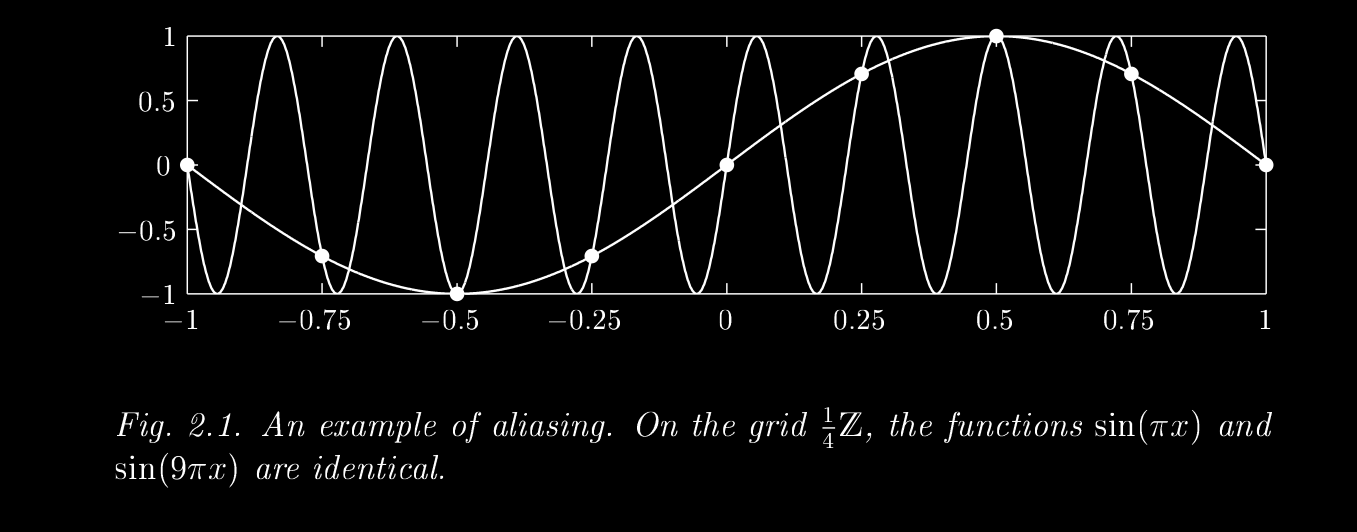

Because infinitely many wavenumbers (aliases) produce the exact same data points on our grid, we must restrict our measurement to a unique interval of length $2\pi/\Delta x$. By convention and for reasons of symmetry, we choose the interval:


$$$$\kappa \in \left[ -\frac{\pi}{\Delta x}, \frac{\pi}{\Delta x} \right]$$$$


The boundaries $\pm \pi/\Delta x$ are the **Nyquist limits**. Any physics occurring at a higher frequency is "folded" back into this range, losing its original identity. 

#### 1.2.1) Aside: Wagon-Wheel Effect

A real life example would be the illusion of car tire moving moving backward, although the car is accelerating. Suppose that sampling rate of our brain is $f_s$- the [flicker-fusion frequency](https://en.wikipedia.org/wiki/Flicker_fusion_threshold) of the human brain, and further suppose that the rate at which the car tire moves is $f$. Take the example, $f=0.9f_s$. Now, our brain perceives the motion as going backward(because each time we close and open our eyes, each spoke would not have completed a full rotation-it will appear to be backward). Whereas, take $f=2f_s$-it will appear to be still(because each time we close and open our eyes, each spoke would have completed a full rotation exactly!). We can summarize the above as:  

## 2) DFT-Discrete Fourier Transform 

In real space, your signal $\psi$ is a vector of $N$ numbers. Each number represents the "strength" of the signal at a specific position $x_n$.

The DFT asks a different question: *"How much of a specific frequency *$\kappa_k$* is present in this set of *$N$* points?"* To answer this, the DFT projects your signal onto a set of $N$** orthogonal complex exponentials**. These exponentials are the "building blocks" of your signal.


$$$$\hat{\psi}_k = \sum_{n=0}^{N-1} \psi_n \underbrace{e^{-i \frac{2\pi}{N} kn}}_{\text{Basis Function}}$$$$


Mathematically, the DFT is a **Matrix-Vector Multiplication**:


$$$$\mathbf{\hat{\psi}} = \mathcal{W} \mathbf{\psi}$$
Where $\mathcal{W}$ is an $N \times N$ matrix.
$$


Because every element in the output vector $\mathbf{\hat{\psi}}$ requires a dot product with a row of $N$ elements, the total number of operations is $N \times N = N^2$. Where the "Fourier Matrix" $\mathcal{W}$ is defined using the roots of unity $W_N = e^{-i 2\pi/N}$:


$$$$\mathcal{W} = \left[ \matrix{ 1 & 1 & 1 & \dots \cr 1 & W_N^1 & W_N^2 & \dots \cr 1 & W_N^2 & W_N^4 & \dots \cr \vdots & \vdots & \vdots & \ddots } \right]$$$$


### 2.1) Inefficiency of DFT

In the $N^2$ approach, the computer is doing a lot of redundant work. For example, $W_N^4$ is just $(W_N^2)^2$. The matrix is full of symmetry and repeating values because the complex exponential is periodic ($$e^{i\theta} = e^{i(\theta + 2\pi)}$$ ).

The "Brute Force" DFT ignores these symmetries and calculates every single interaction as if it were brand new. This is why for $N=1024$, you hit a million operations—most of which are just re-calculating the same rotations over and over.

If you look at the $N=4$ case, the matrix is highly symmetrical:


$$\mathcal{W}_4 = \left[ \matrix{ 1 & 1 & 1 & 1 \cr 1 & -i & -1 & i \cr 1 & -1 & 1 & -1 \cr 1 & i & -1 & -i } \right]$$


Notice that the values $1, -1, i, -i$ repeat constantly. The standard DFT ignores this and recalculates every multiplication from scratch-time complexity is $O(N^2)$. To overcome this, we have the **FFT** (Fast Fourier Transform).

## 3) FFT-Fast Fourier Transform

### **3**.**1) The Strategy: Divide and Conquer**

If $N$ is a power of 2 ($$N=2^m$
$), the FFT recursively splits the $N$-point DFT into two smaller $N/2$-point DFTs: one for the **even-indexed** points ($$x_0, x_2, \dots$$) and one for the **odd-indexed** points ($$x_1, x_3, \dots$$).


$$$$\hat{\psi}_k = \text{DFT}_{Even}(k) + e^{-i\frac{2\pi}{N}k} \cdot \text{DFT}_{Odd}(k)$$$$


By doing this, the algorithm realizes that the values needed to compute the first half of the frequencies ($$0$ to $N/2-1$$) are almost identical to those needed for the second half ($$N/2$ to $N-1$$).

## 3.2) The "Butterfly" operation

The real magic happens because of **symmetry**. When you calculate the first half of your frequencies ($$k < N/2$
$), you use the formula above. When you calculate the second half ($$k \geq N/2$),$ the complex exponential $e^{-i 2\pi k/N}$ simply **flips its sign**.

This means:

- **Top Half (**$$k$$**):** $\text{Even} + (\text{Exponential} \times \text{Odd})$

- **Bottom Half (**$$k+N/2$$**):** $\text{Even} - (\text{Exponential} \times \text{Odd})$

Instead of doing two separate calculations, the computer does **one** multiplication and uses the result for **two** different frequencies. This "X" pattern is called a **Butterfly**.

## 3.3) Reduction in Complexity

The FFT doesn't stop at one split. It splits the 4-point groups into 2-point groups, and so on, until it is only doing simple 2-point additions.

- **The "Width":** At every stage, you are still processing $N$ points.

- **The "Depth":** The number of times you can split $N$ in half is $\log_2 N$.(You are encouraged to check why!)

For $N = 1024$ ($$2^{10}$$):

- **DFT:** $1024 \times 1024 \approx 1,000,000$ operations.

- **FFT:** $10 \text{ stages} \times 1024 \text{ points} \approx 10,240$ operations.

As you see, the change in complexity is from $O(N^2)$ to $O(N \log N)$. Summarizing:

## 4) When does FFT lose its edge-(People concerned with HPC)?

### **4.1) When **$N$** is a Large Prime Number**

The "Divide and Conquer" strategy (Cooley-Tukey) depends on $N$ being highly composite (ideally a power of 2, like 256, 512, 1024).

- **The Power of 2:** The algorithm splits the $N$ points perfectly into $N/2$, then $N/4$, all the way down to 2.

- **The Prime Problem:** If $N = 1031$ (a prime number), the algorithm cannot split the data into even/odd pairs.

Modern libraries (like FFTW used by MATLAB) use **CZT(**[**Chirp Z-Transform(Wiki)**](https://en.wikipedia.org/wiki/Chirp_Z-transform)** or **[**MATLAB official document about CZT**](https://in.mathworks.com/help/signal/ug/chirp-z-transform.html)**)** to handle primes, which involves padding the data to a power of 2, performing the FFT, and then "trimming" it. While this stays $O(N \log N)$, the overhead makes it notably slower than a "clean" power-of-2 FFT(The Cooley-Tukey Algorithm) 

Best thing to do will be to choose a highly composite power of 2. 

### **4.2) The Memory Bottleneck (The Cache Miss)**

The FFT is highly efficient in terms of CPU cycles, but it requires a lot of "data shuffling" (Bit-Reversal Permutation) to organize the even and odd samples.

- As $N$ becomes massive (e.g., $N > 10^7$), the data no longer fits in the CPU's **L1/L2 Cache**.

- The CPU must constantly fetch data from the much slower **RAM**.

- At this point, the "sluggishness" isn't caused by the math, but by the physical speed of moving bits across the motherboard.

#### Solution? 

There are multiple different algorithms, suited for different needs, optimized for different hardware constraints. The `fftw() (`FFT in the West`)`library developed in MIT. It adapts the DFT algorithm to details of the underlying hardware in order to maximize performance. Hence, the computation of the transform is split into two phases. First, FFTW’s planner “learns” the fastest way to compute the transform on your machine. The planner produces a data structure called a plan that contains this information. Subsequently, the plan is executed to transform the array of input data as dictated by the plan. FFTW supports transforms of data with arbitrary length, rank, multiplicity, and a general memory layout. In simple cases, however, this generality may be unnecessary and confusing([FFTW Documentation](https://www.fftw.org/fftw3.pdf) or visit the [Homepage of FFTW](https://www.fftw.org/) and find documentation there).

## **4.3) Extremely Small **$N$

For a tiny grid, say $N = 8$ or $N = 16$:

- **Manual DFT:** $8^2 = 64$ operations.

- **FFT:** $8 \log_2 8 = 24$ operations.

At this scale, the **administrative overhead** of the FFT (setting up the recursion, allocating memory, twiddle factor lookups) can actually take more time than the "brute force" approach. For $N < 16$, a hard-coded manual DFT matrix might actually be faster in raw execution time.

#### Note: However, most of the issues are in the domain of HPC-High Performance Computing. For our base-case use, we will not be dealing with such issues. 

Now, we shall move to the coding part... 

# Coding/Numerics

We will deal with the simple case of performing an FFT and the inverse FFT and then plotting it. 

## 1) Define Parameters and initialization

L = 100;                 % Domain length
N = 1024;                % Number of points
dx = L/N;                % Grid spacing
x = (0:N-1)*dx;          % Space vector

% Pulse A: Centered at 30, vibrating at k=2
pulseA = exp(-(x-30).^2/20) .* cos(2 * x); 

% Pulse B: Centered at 70, vibrating at k=8
pulseB = exp(-(x-70).^2/10) .* cos(8 * x);

%Combined Pulse
psi = pulseA + pulseB;

## 2) Performing FFT and Defining k-modes(Recall Nyquist Limit)

% Define the Wavenumbers (k)
% Recall: k = 2*pi/L * [0:N/2-1, -N/2:-1] 
dk = 2*pi/L;
k = dk * [0:N/2-1, -N/2:-1];

%Performing FFTs
psi_hat = fft(psi);
k_plot = fftshift(k);
mag_plot = fftshift(abs(psi_hat));

#### Why is the array peculiarly ordered?

## 3) Plotting

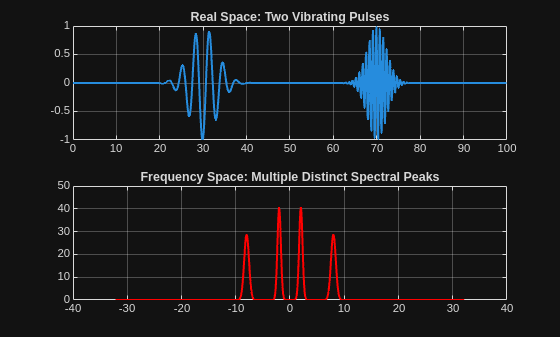

figure;
subplot(2,1,1); plot(x, psi, 'LineWidth', 1.5); 
title('Real Space: Two Vibrating Pulses'); grid on;

subplot(2,1,2); plot(k_plot, mag_plot, 'r', 'LineWidth', 1.5); 
title('Frequency Space: Multiple Distinct Spectral Peaks'); grid on;

#### Note:  

1) Since our k-modes are stored as `[0,positives, negatives], fftshift() `orders the function such that it simply swaps the left and right halves of the vector.

- **Before shift:** `[Positives, Negatives]`

- **After shift:** `[Negatives, 0, Positives]`

`For Another Function,, we will get the following output:`


$$u=e^{-sin(x/2)^2}$$